# Tarea 1 método Runge Kutta 4rto orden

## Ejercicio 1

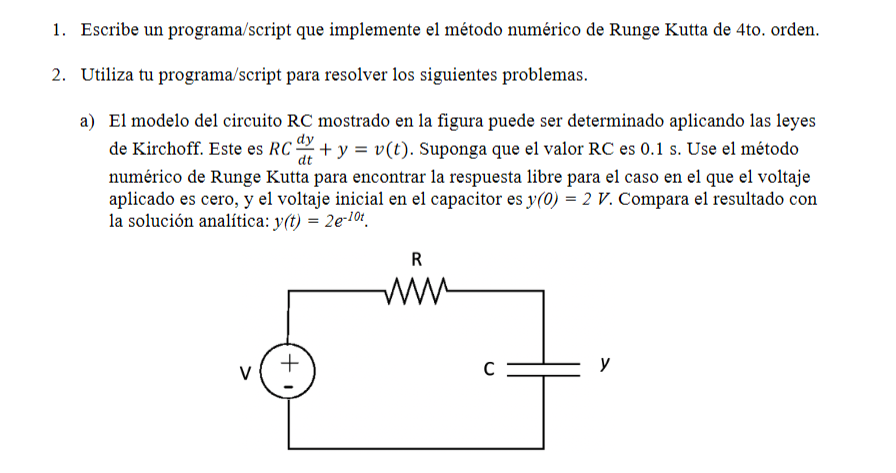

clear ();
clc
f=@(x,y) (-y)*10;
x=[0:.01:1];
y=2*exp(-10*x);
x0=0;
y0=2;
xn=1;

h=.01;
fprintf("\n x          y: ");


 x          y: 

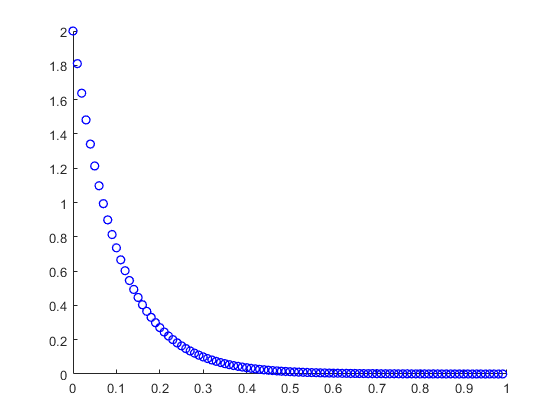

0.000   2.000000 
0.010   1.809675 
0.020   1.637462 
0.030   1.481637 
0.040   1.340641 
0.050   1.213062 
0.060   1.097624 
0.070   0.993171 
0.080   0.898659 
0.090   0.813140 
0.100   0.735760 
0.110   0.665743 
0.120   0.602389 
0.130   0.545064 
0.140   0.493195 
0.150   0.446261 
0.160   0.403794 
0.170   0.365368 
0.180   0.330598 
0.190   0.299138 
0.200   0.270671 
0.210   0.244913 
0.220   0.221607 
0.230   0.200518 
0.240   0.181436 
0.250   0.164170 
0.260   0.148548 
0.270   0.134411 
0.280   0.121620 
0.290   0.110047 
0.300   0.099574 
0.310   0.090099 
0.320   0.081525 
0.330   0.073767 
0.340   0.066747 
0.350   0.060395 
0.360   0.054648 
0.370   0.049447 
0.380   0.044742 
0.390   0.040484 
0.400   0.036631 
0.410   0.033145 
0.420   0.029991 
0.430   0.027137 
0.440   0.024555 
0.450   0.022218 
0.460   0.020104 
0.470   0.018191 
0.480   0.016460 
0.490   0.014893 
0.500   0.013476 
0.510   0.012194 
0.520   0.011033 
0.530   0.009983 
0.540   0.009033 
0.550   0.

figure(2)
hold on
while x0<xn
    fprintf("\n%4.3f   %4.6f \n",x0,y0);
    k1=f(x0,y0);
    k2=f(x0+h*.5,y0+h*k1*.5);
    k3=f(x0+h*.5,y0+h*k2*.5);
    k4=f(x0+(h),y0+h*k3);
    y1=y0+h*(k1+2*k2+2*k3+k4)/6;
    plot(x0,y0,"-ob","LineWidth",1)
    x0=x0+h;
    y0=y1;
   
end

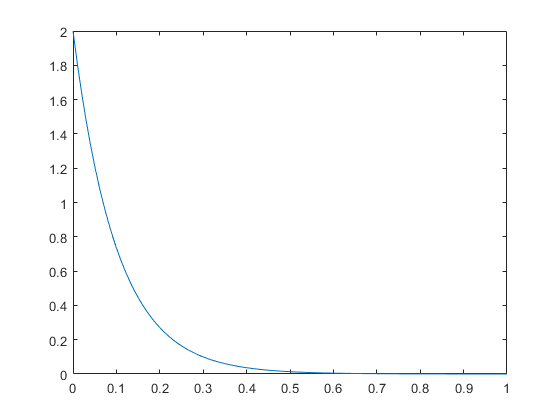

fprintf("\n");
figure(3)
plot(x,y)

## Ejercicio 2

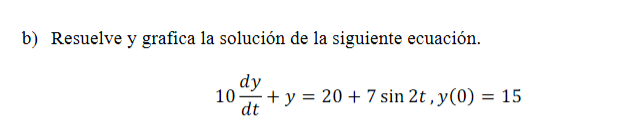

clear ();
clc
f=@(x,y) (-y/10)+10+(7/10)*sin(2*x);
x0=0;
y0=15;
xn=40;

h=.05;
fprintf("\n x          y: ");


 x          y: 

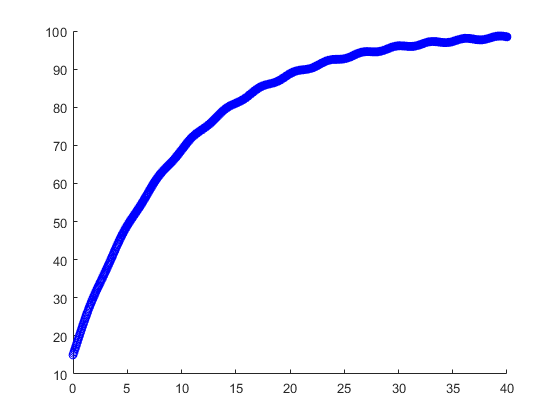

0.000   15.000000 
0.050   15.425685 
0.100   15.852718 
0.150   16.281039 
0.200   16.710557 
0.250   17.141146 
0.300   17.572648 
0.350   18.004877 
0.400   18.437619 
0.450   18.870632 
0.500   19.303654 
0.550   19.736401 
0.600   20.168571 
0.650   20.599850 
0.700   21.029912 
0.750   21.458420 
0.800   21.885039 
0.850   22.309427 
0.900   22.731250 
0.950   23.150176 
1.000   23.565884 
1.050   23.978067 
1.100   24.386434 
1.150   24.790710 
1.200   25.190646 
1.250   25.586015 
1.300   25.976617 
1.350   26.362282 
1.400   26.742870 
1.450   27.118272 
1.500   27.488415 
1.550   27.853259 
1.600   28.212797 
1.650   28.567060 
1.700   28.916112 
1.750   29.260050 
1.800   29.599006 
1.850   29.933143 
1.900   30.262655 
1.950   30.587765 
2.000   30.908721 
2.050   31.225796 
2.100   31.539285 
2.150   31.849500 
2.200   32.156770 
2.250   32.461436 
2.300   32.763846 
2.350   33.064358 
2.400   33.363327 
2.450   33.661111 
2.500   33.958060 
2.550   34.254518 
2.600   34.5

figure
hold on
while x0<xn
    fprintf("\n%4.3f   %4.6f \n",x0,y0);
    k1=f(x0,y0);
    k2=f(x0+h*.5,y0+h*k1*.5);
    k3=f(x0+h*.5,y0+h*k2*.5);
    k4=f(x0+(h),y0+h*k3);
    y1=y0+h*(k1+2*k2+2*k3+k4)/6;
    plot(x0,y0,"-ob")
    x0=x0+h;
    y0=y1;
   
end

fprintf("\n");

